# Circuit Demo

The purpose of this file is to demonstrate Laplace domain matching of cascaded S-parameters. Two circuits are created, fit with a rational function, and then are cascaded into a two port network which can optimized for.

## Create the first circuit

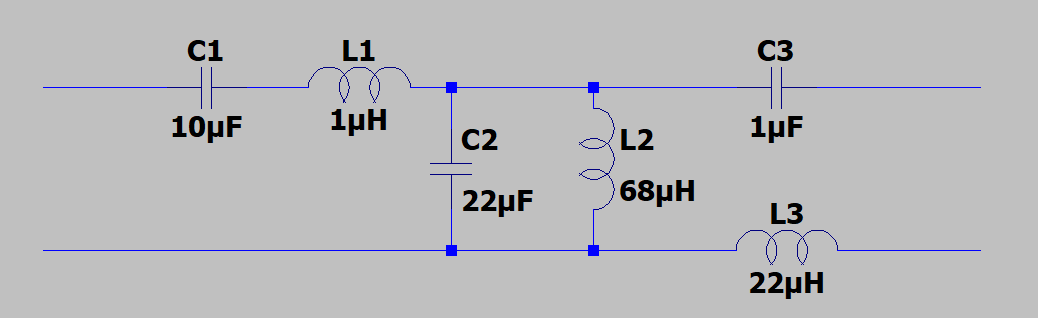

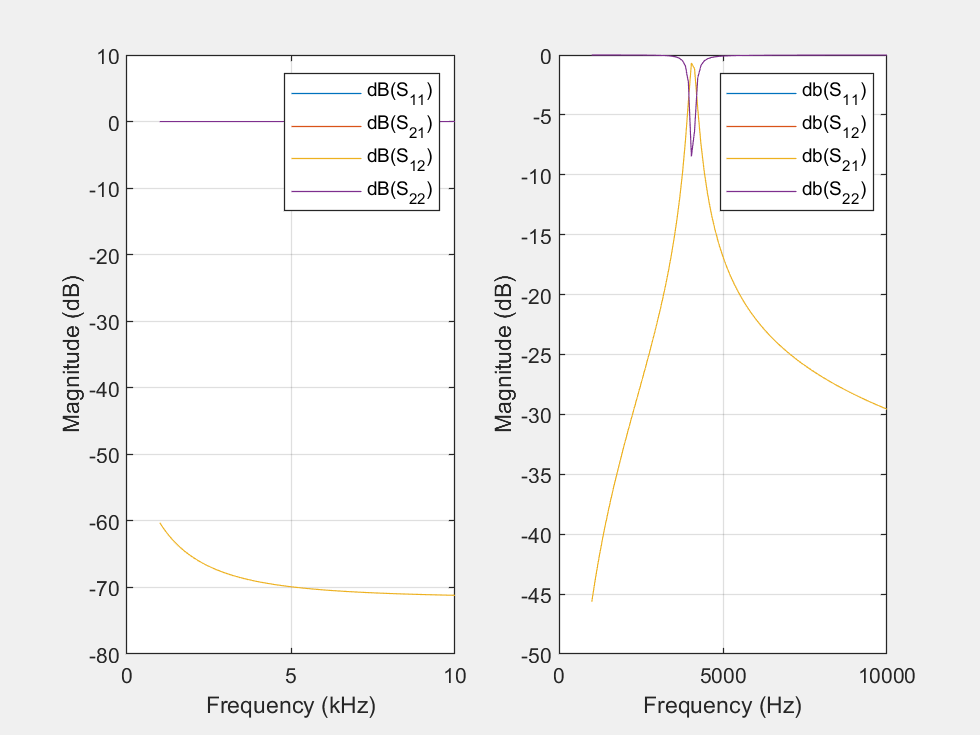

cir1 = circuit('Circuit1');
add(cir1, [1, 2], capacitor(10e-6));
add(cir1, [2, 3], inductor(1e-6));
add(cir1, [3, 4], inductor(68e-6));
add(cir1, [3, 4], capacitor(22e-6));
add(cir1, [3, 5], capacitor(1e-6));
add(cir1, [4, 6], inductor(22e-6));
setports(cir1, [1, 4], [5, 6]);

freqs = logspace(3, 4, 100);
s1 = sparameters(cir1, freqs);
rfplot(s1); xscale('linear'); title('Circuit 1');
fit1 = rational(s1, 'TendsToZero', false, 'MaxPoles', 6);
F1 = freqresp(fit1, freqs);
plot(freqs, db(squeeze(F1(1,1,:))), freqs, db(squeeze(F1(1,2,:))), ...
    freqs, db(squeeze(F1(2,1,:))), freqs, db(squeeze(F1(2,2,:)))); xscale('linear'); grid on;
legend('db(S_1_1)', 'db(S_1_2)', 'db(S_2_1)', 'db(S_2_2)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');

## Create the second circuit

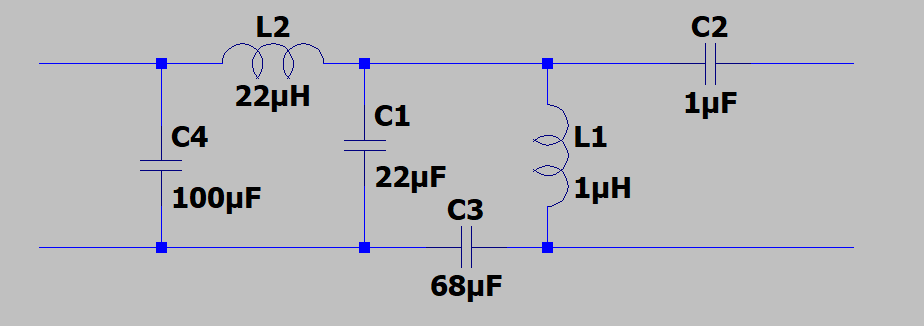

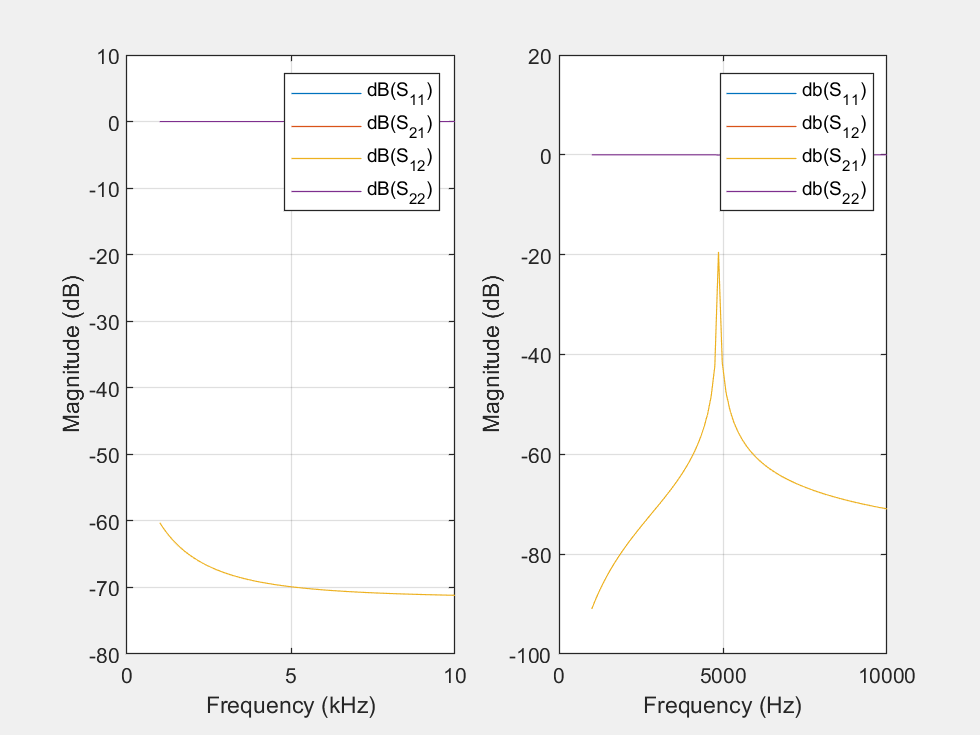

cir2 = circuit('Circuit2');
add(cir2, [1, 2], capacitor(100e-6));
add(cir2, [1, 3], inductor(22e-6));
add(cir2, [3, 2], capacitor(22e-6));
add(cir2, [3, 4], inductor(1e-6));
add(cir2, [2, 4], capacitor(68e-6));
add(cir2, [3, 5], capacitor(1e-6));
setports(cir2, [1, 2], [4, 5]);

s2 = sparameters(cir2, freqs);
rfplot(s2); xscale('linear'); title('Circuit 2');
fit2 = rational(s2, 'TendsToZero', false, 'MaxPoles', 6);
F2 = freqresp(fit2, freqs);
plot(freqs, db(squeeze(F2(1,1,:))), freqs, db(squeeze(F2(1,2,:))), ...
    freqs, db(squeeze(F2(2,1,:))), freqs, db(squeeze(F2(2,2,:)))); xscale('linear'); grid on;
legend('db(S_1_1)', 'db(S_1_2)', 'db(S_2_1)', 'db(S_2_2)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');

## Cascaded Circuits

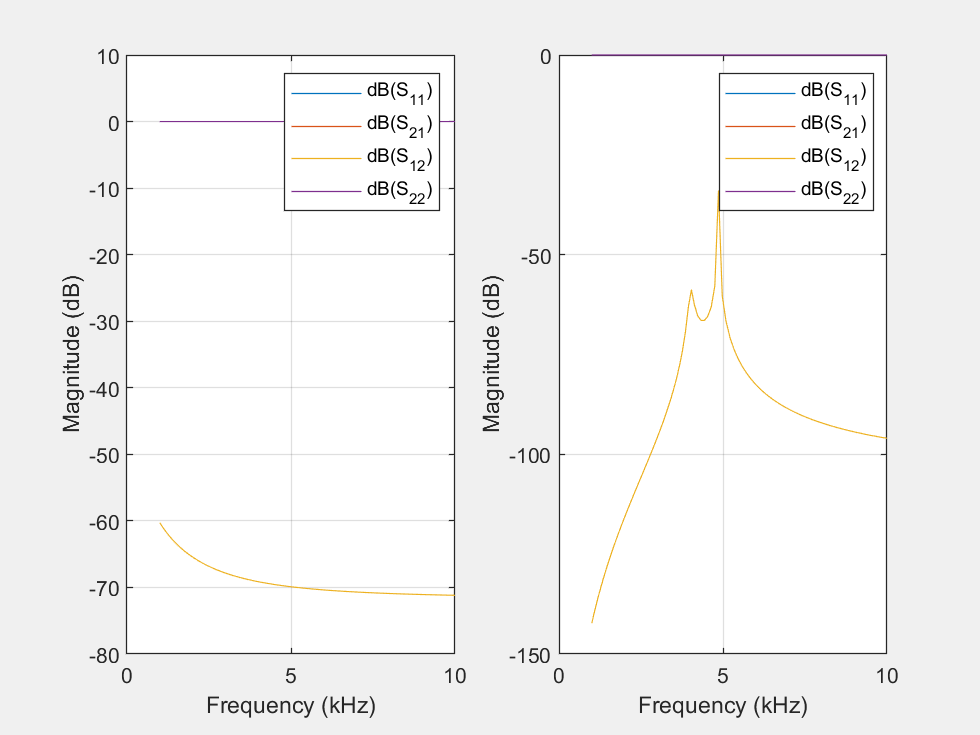

s = cascadesparams(s1, s2);
rfplot(s);

## Optimize for this cascaded circuit

sz = [1, 2, 1, 2];
networks = fpg(sz);
err = [squeeze(abs(s.Parameters(1, 1, :))) ...
       squeeze(abs(s.Parameters(1, 2, :))) ...
       squeeze(abs(s.Parameters(2, 2, :))), ...
       squeeze(angle(s.Parameters(1, 1, :))), ...
       squeeze(angle(s.Parameters(1, 2, :))), ...
       squeeze(angle(s.Parameters(2, 2, :)))];

obj = @(x, xdata) synobj(x, sz, xdata);
constr = @(x) synconstr(x, sz);

nvar = 13*sum(networks.^2+networks)/2;
stx = rand(1, nvar);


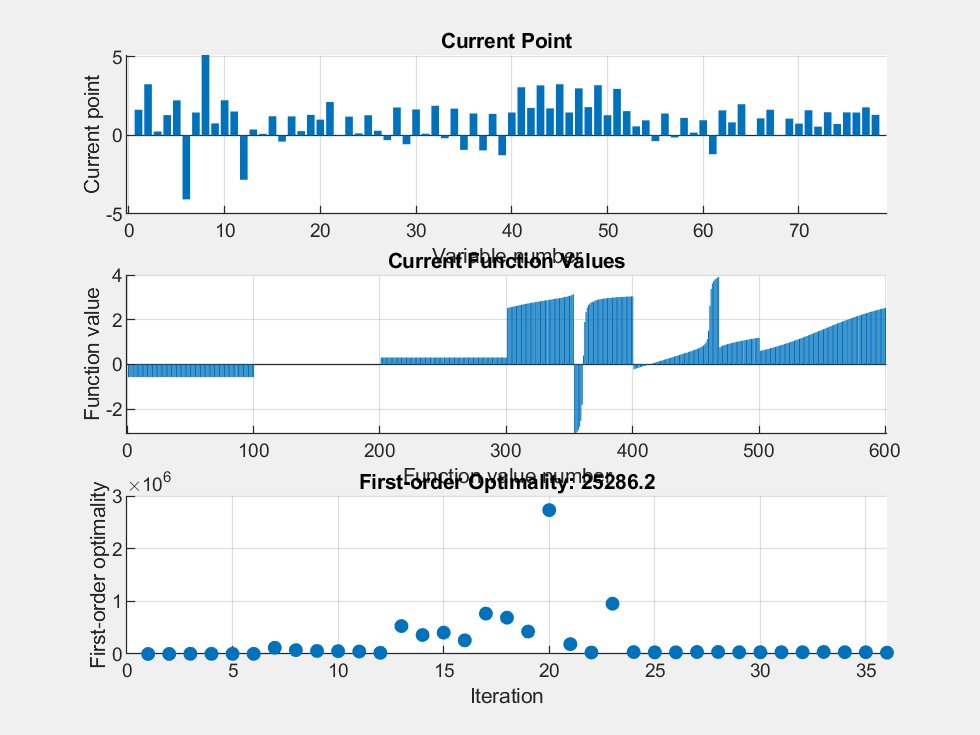


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



% Set nondefault solver options
options = optimoptions("lsqcurvefit","UseParallel",true,"PlotFcn",...
    ["optimplotx","optimplotfval","optimplotfirstorderopt"]);

% Solve
[solution,objectiveValue] = lsqcurvefit(obj,stx,freqs,err,repmat(-100,...
    size(stx)),repmat(100,size(stx)),[],[],[],[],constr,options);


% Clear variables
clearvars options

## Plot the Results

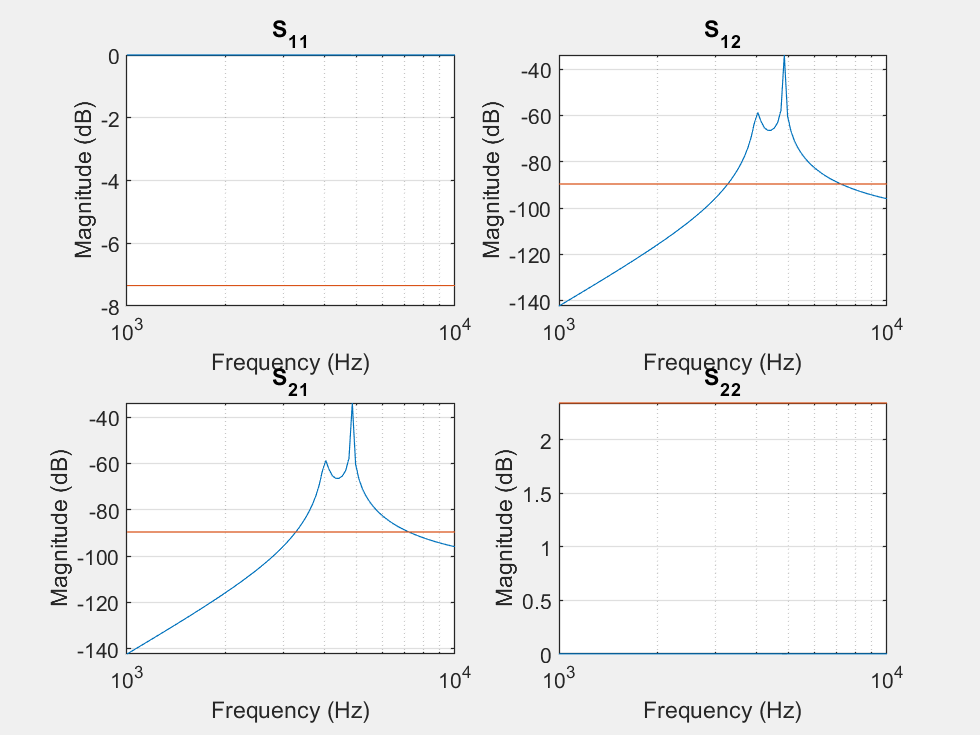

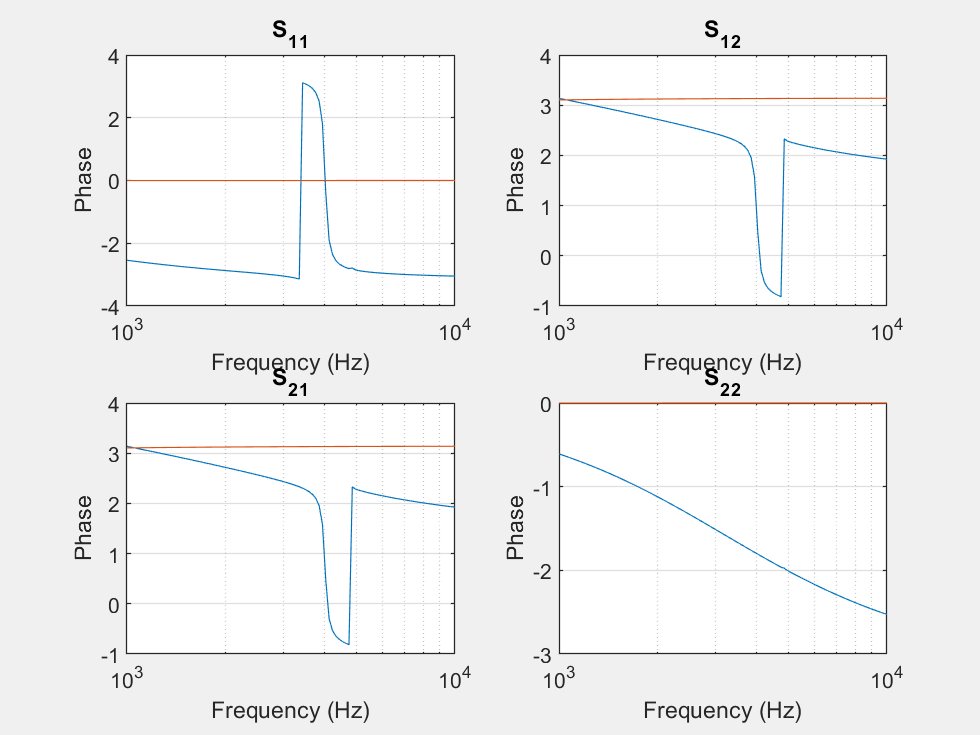

G = casctran(solution, sz);
H = tsc(G, sz);
F = frd(H, freqs, 'FrequencyUnit', 'Hz');
for ii = 1:4
    [row, col] = ind2sub([2, 2], ii);
    subplot(2, 2, ii);
    plot(freqs, reshape(db(s.Parameters(row, col, :)), 1, []), freqs, reshape(db(F.ResponseData(row, col, :)), 1, []));
    xscale('log'); xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
    % legend('Input', 'Synthesis');
    title(['S_' num2str(col) '_' num2str(row)]); grid on;
end
for ii = 1:4
    [row, col] = ind2sub([2, 2], ii);
    subplot(2, 2, ii);
    plot(freqs, reshape(angle(s.Parameters(row, col, :)), 1, []), freqs, reshape(angle(F.ResponseData(row, col, :)), 1, []));
    xscale('log'); xlabel('Frequency (Hz)'); ylabel('Phase');
    % legend('Input', 'Synthesis');
    title(['S_' num2str(col) '_' num2str(row)]); grid on;
end

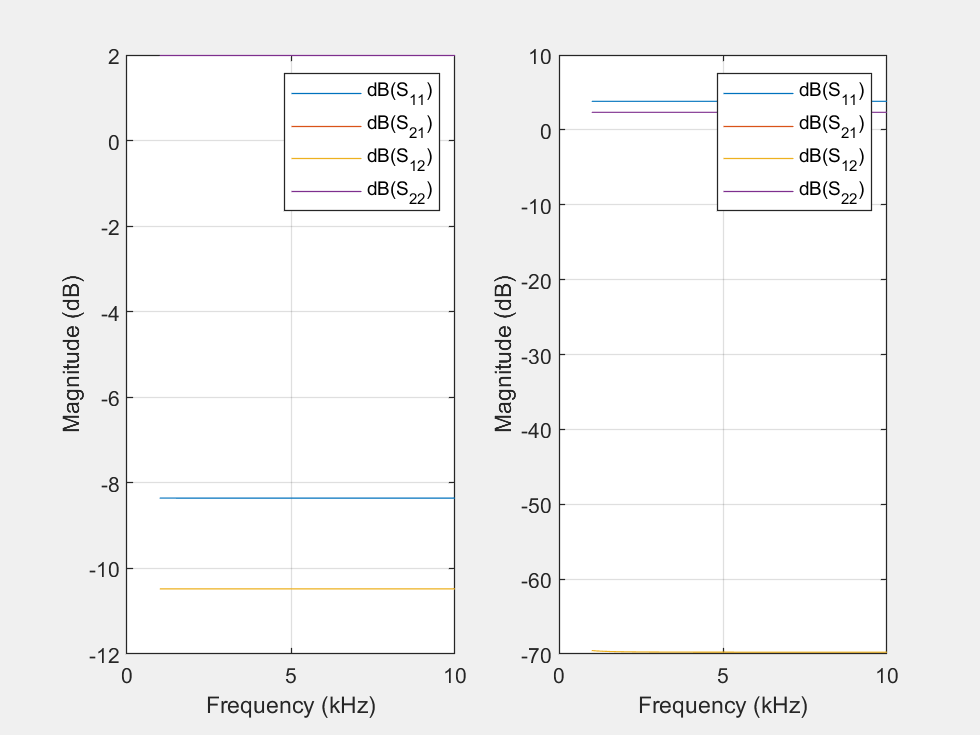

for ii = 1:sz(1)*sz(2)
    subplot(sz(1), sz(2), ii);
    T = sparameters(freqresp(G{ii}, freqs), freqs);
    rfplot(T);
end